clc; clear; close all;

## Radar Parameters

**Q1) **Is the sampling rate fs sufficient to respect Nyquist criterion for all signals in the block diagram?

B = 200e6;       % Chirp bandwidth (Hz)
T = 0.1e-3;       % Chirp duration (s)
f0 = 50e6;      % Carrier frequency of the RF signal (Hz) 
fs = 500e6;     % Sampling rate of all the signals in this simulation (Hz) 
c = 3e8;        % Speed of light (m/s)


  **  ! f0 CHANGED TO 150 MHz !**

**    Reasoning (Satisfying Nyquist and the bandwidth condition) :**

    Fs(given) = 500MHz 

    B(given) = 200MHz

    Fmax = Fs/2 (Nyquist) = 250MHz

    F0 = Fmax - B = 50MHz

    minus B because the central frequency is not defined here as the middle of the bandwidth, it is the very first frequency of the band. 

## Target Parameters

R_target = [5,8,12];  % Target distance (m)
tau = 2 * R_target / c; % Time delay (s)

## Time Vectors

t = 0:1/fs:(T-1/fs);  % Time vector for one chirp
N = length(t); % Number of time samples in one chirp

## Signal Generator - Chirp generation (Base Band)

**Q2)** Pay attention at the definition of the chirp in line 12 as a complex exponential. How to plot then the usual cosine-like function?

**Q3)** Pay attention to the definition of the frequency axis in line 17 and the related instruction on line 21. Why do we limit the visible frequency to max 100 Hz? Feel free to zoom in more closer to 0 Hz if needed.

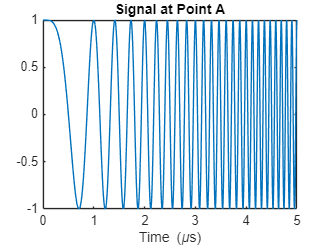

k = B / T;     % Chirp slope defined as ratio of bandwidth over duration
sig_A = exp(1j*2*pi*(0.5*k*t.^2));
sig_A_fft=fft(sig_A);
figure;
plot(t*1e6, real(sig_A)); title('Signal at Point A'); xlabel('Time (\mus)');
xlim([0 5])

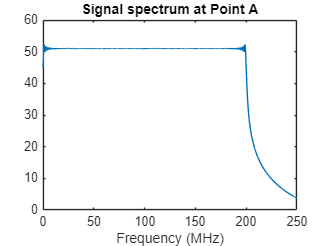

freqaxis=linspace(0,fs,length(sig_A_fft)); %in Hz
figure;
plot(freqaxis.*1e-6,20*log10(abs(sig_A_fft))); 
title('Signal spectrum at Point A'); xlabel('Frequency (MHz)');
xlim([0 (fs/2)*1e-6])

## Generate FMCW Chirp Signal (RF)

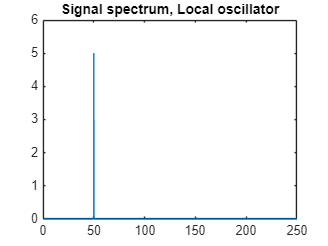

lo = exp(1j*2*pi*f0*t);    % Local oscillator emitting a single tone
figure;
plot(freqaxis.*1e-6,1e-4*abs(fft(lo)))
title('Signal spectrum, Local oscillator'); 
xlim([0 (fs/2)*1e-6])

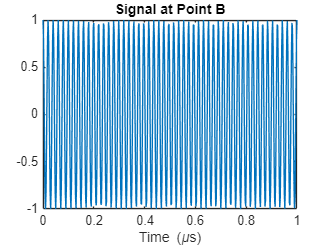


s_tx = sig_A .* lo;        % Mixing is a multiplication. Ignore the BPF here as we are in ideal conditions, nothing to filter away
sig_B=s_tx;
figure;
plot(t*1e6, real(sig_B)); title('Signal at Point B'); xlabel('Time (\mus)');
xlim([0 1])

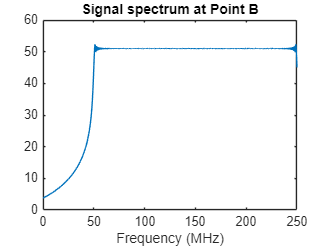

sig_B_fft=fft(sig_B);

figure;
plot(freqaxis.*1e-6,20*log10(abs(sig_B_fft)))
title('Signal spectrum at Point B'); 
xlabel('Frequency (MHz)');
xlim([0 (fs/2)*1e-6])

## Generate Received Signal (via a delay and free-space path loss)

**Q4)** `Can you explain to each other what this section of the code does? What can be the role of this for-loop? Hint: think of multi target cases...`

s_rx=0;
for ii=1:length(R_target)
    t_delayed = t - tau(ii);  % Time-shifted version of time vector
    attenuation = (1/((4*pi*(R_target(ii))^2)^2)) / (1/((4*pi*(R_target(1))^2)^2)) %Free space path loss, normalized to the first target.
    s_rx = s_rx+ attenuation * exp(1j * 2 * pi * (f0 * t_delayed + (k/2) * t_delayed.^2));  % Received signal
end

attenuation = 1

attenuation = 0.1526

attenuation = 0.0301

## Mix Signals to Get Beat Frequency

**Q5)** Make sure you recognize the operations in lines 39-40 and can map them to the block diagram of FMCW radar seen in the lectures. If in doubt, do ask.  

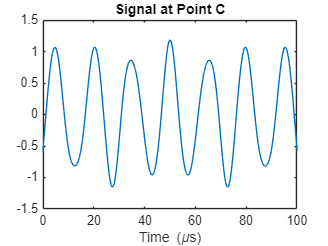

s_beat = s_rx .* conj(s_tx); % Mixing 
s_beat = lowpass(real(s_beat), B, fs); % Low-pass filter
sig_C=s_beat;
figure;
plot(t*1e6, s_beat); title('Signal at Point C'); xlabel('Time (\mus)');
xlim([0 100])

## FFT analysis for Range Estimation

**Q6) **Does what you see match the expected beatnote frequency computed at point A of exercise 3? Yes/no why? What happens to the last 2 figures if you change the bandwidth B of your chirp?

**Q7) **Check the zero padding operation on line 44-45 and recall from the preparatory video the effect of zero padding. You can (not compulsory but helpful) play with the number of FFT points by zero padding more/less and checking the effect on the range profile plot.

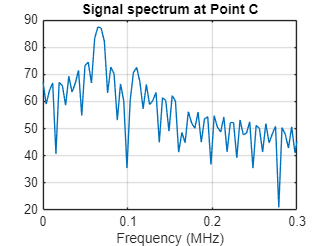

N_fft = 2^nextpow2(N)*2;  % Zero-padding to sample more points in frequency/range 
S_beat_FFT = abs(fft(s_beat, N_fft));  % Compute FFT
sig_C_fft= S_beat_FFT;  % Compute FFT without zero padding

freqaxis_beat=linspace(0,fs,length(S_beat_FFT)); %in Hz
figure;
plot(freqaxis_beat.*1e-6,20*log10(abs(S_beat_FFT)))
title('Signal spectrum at Point C'); xlabel('Frequency (MHz)');
xlim([0 0.3]);
grid on;

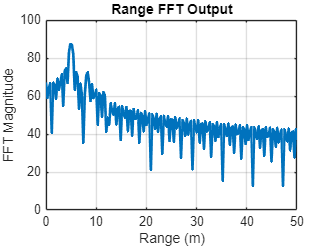


range_axis_beat = (c * freqaxis_beat) / (2 * k);  % Convert beat frequency to range
plot(range_axis_beat, 20*log10(abs(S_beat_FFT)), 'LineWidth', 2);
xlabel('Range (m)'); ylabel('FFT Magnitude');
title('Range FFT Output');
%xlim([0 350]); % Focus on relevant range where you have targets
xlim([0,50])
xticks(linspace(0,50, 6))
grid on;